# **Homework 2 Orbital Dynamics - Interplanetary flight**

Student 1: Mario Barrantes Mellado 100471762

Student 2: Artem Lorenzo Lymar 100471784

The date is January 1, 2312. A spaceship is planning a trip from Venus (B) low orbit to Mercury (A) low orbit, with the data below:

close all; clear all; clc;

% Parameters of orbit around Venus
a_V = 10000; % 
e_V = 0; % circular orbit
Omega_V = deg2rad(30); % [deg]->[rad] 
i_V = deg2rad(15); % [deg]->[rad] 

% Parameters of orbit around Mercury
a_M = 10000; % 
e_M = 0; % circular orbit
Omega_M = deg2rad(50); % [deg]->[rad] 
i_M = deg2rad(-40); % [deg]->[rad] 

% Gravitational Parameters
mu_V = 3.24859e5;  % [km^3/s^2] - not needed for heliocentric problem
mu_M = 0.220318e5; % [km^3/s^2] - not needed for heliocentric problem
mu_S = 1327120e5;  % [km^3/s^2]

### a) Implement the following functions

####     i) Dt = tof(mu,a,e,theta1,theta2)

% theta1 = deg2rad(10); % [deg]->[rad] 
% theta2 = deg2rad(30); % [deg]->[rad] 
% 
% Dt = functionshw2.tof(mu_V, a_V, e_V, theta1, theta2); % Time of travel between theta1 and theta2 [s]
% fprintf('\nTime of flight = %.4f s = %.4f days\n', Dt, Dt/86400);

#### **    ii) [a,e,Omega,i,omega,theta1,theta2] = Lambert conic(r1,r2,eT,k)**

    Function to compute the COE of the transfer trajectory (with a in km and angles in rad) between position vectors r1 and r2 (in km), as a function of the transverse eccentricity component, eT. Vector k defines the positive direction of the orbital plane normal and therefore selects between short and long arc solutions.

% r1 = [8945.34;5000;3000]; %km
% r2 = [7214.83899;2000;8249.64731]; %km
% eT = 0.4; %
% k = cross(r1,r2)/norm(cross(r1,r2)); % Normal vector to orbit plane
% 
% [a, e, Omega, i, omega, theta1, theta2] = functionshw2.Lambert_conic(r1, r2, eT, k);

#### **     iii) [a,e,Omega,i,omega,theta1,theta2] = Lambert solve(mu,r1,r2,Dt,k)**

Solve Lambert’s problem using the previous two functions. Internally, the function should use the bisection method. Restrict the search to elliptic solutions. The units of input and output arguments just be the same as in previous functions.

% Dt = functionshw2.tof(mu_V, a, e, theta1, theta2);
% fprintf('\nTarget time of flight = %.4f s\n', Dt);
% 
% [a_s, e_s, Omega_s, i_s, omega_s, theta1_s, theta2_s, eT_lambert] = functionshw2.Lambert_solve(mu_V, r1, r2, Dt, k);
% 
% fprintf('Lambert_solve results:\n');
% fprintf('a = %.4f km\n', a_s);
% fprintf('eTlambert = %.4f\n', eT_lambert);
% fprintf('e = %.6f\n', e_s);
% fprintf('Omega = %.4f deg\n', rad2deg(Omega_s));
% fprintf('i = %.4f deg\n', rad2deg(i_s));
% fprintf('omega = %.4f deg\n', rad2deg(omega_s));
% fprintf('theta1= %.4f deg\n', rad2deg(theta1_s));
% fprintf('theta2= %.4f deg\n', rad2deg(theta2_s));
% 
% % tof matches input Dt?
% Dt_check = functionshw2.tof(mu_V, a_s, e_s, theta1_s, theta2_s);
% fprintf('Verification: tof(solution) = %.4f s  (target = %.4f s)\n', ...
%     Dt_check, Dt);
% fprintf('Error = %.6f s\n', abs(Dt_check - Dt));

To verify Lambert_solve is correct we build a test case using `r1`, `r2` and `Dt` derived from a known orbit with `eT = 0.4 `(from question a.ii). The solver correctly recovers the same orbital elements and time of flight, therefore this function is OK.

### b) [theta, Dv] = hyperbola(mu, a, e, Omega, i, omega, $\textbf{v}_h$)

To find the parking orbit true anomaly, $\theta$ (rad), and the injection impulse vector, $\Delta \text{v}$ (km/s.), to go from parking orbit to escape hyperbola.

% r_park = 5000; % radius of parking orbit [km] = pericenter of hyperbolic scape trajectory
% e_park = 1; % parking orbit is circular
% a_park = r_park; % parking orbit is circular 
% mu_park = mu_V; % change depending on central body
% vh_park = sqrt(-mu_park/a_park); % hyperbolic excess velocity [km/s] - must be a vector!!
% Omega_park = 1; %[rad]
% i_park = 1; %[rad]
% omega_park = 1; %[rad]
% 
% [theta, Dv] = functionshw2.hyperbola(mu_park, a_park, e_park, Omega_park, i_park, omega_park, vh_park);

### c) meshgrid 

`from Horizons Database`

`2312-Jan-01 (wrt to solar system barycenter)`

`      EC     Eccentricity, e`

`      QR     Periapsis distance, q (km)`

`      IN     Inclination w.r.t X-Y plane, i (degrees)`

`      OM     Longitude of Ascending Node, OMEGA, (degrees)`

`      W      Argument of Perifocus, w (degrees)`

`      Tp     Time of periapsis (Julian Day Number)`

`      N      Mean motion, n (degrees/sec)`

`      MA     Mean anomaly, M (degrees)`

`      TA     True anomaly, nu (degrees)`

`      A      Semi-major axis, a (km)`

`      AD     Apoapsis distance (km)`

`      PR     Sidereal orbit period (sec)`

### `Venus``:`

`Position & velocity wrt solar system barycenter`

`X =-6.477298847799687E+07 Y =-8.589866827531046E+07 Z = 2.487725783413380E+06`

`VX= 2.763672319058894E+01 VY=-2.134982207311649E+01 VZ=-1.898103269009142E+00`

`COE`

`EC= 1.405226716152621E-02 QR= 1.051046316043030E+08 IN= 3.394665537649070E+00`

`OM= 7.592535133903603E+01 W = 2.407441806744838E+01 Tp=  2565419.138491620775`

`N = 1.897649917606026E-05 MA= 1.317582804277378E+02 TA= 1.329454994607601E+02`

`A = 1.066026403871473E+08 AD= 1.081006491699916E+08 PR= 1.897083316896284E+07`

% Collecting data from Horizons Database
r_V0 = [-6.477298847799687E+07;-8.589866827531046E+07;2.487725783413380E+06]; %[km] wrt to solar center barycenter
v_V0 = [2.763672319058894E+01;-2.134982207311649E+01;-1.898103269009142E+00]; %[km/s]

e_V0 = 1.405226716152621E-02;              % Eccentricity [-]
Omega_V0 = deg2rad(7.592535133903603E+01); % RAAN [rad]
rp_V0 = 1.051046316043030E+08;             % Periapsis distance [km]
ra_V0 = 1.081006491699916E+08;             % Apoapsis distance [km] 
i_V0 = deg2rad(3.394665537649070E+00);     % Inclination [rad]
omega_V0 = deg2rad(2.407441806744838E+01); % Argument of periapsis [rad]
a_V0 = 1.066026403871473E+08;              % Semimajor axis [km]
theta_V0 = deg2rad(1.329454994607601E+02); % True anomaly [rad]
t_V0 = 1.897083316896284E+07;              % Sidereal orbit period [s]

### `Mercury``:`

`Position & velocity wrt solar system barycenter`

`X = 5.045410505191125E+07 Y = 1.167075906445298E+07 Z =-3.612451197805805E+06`

`VX=-2.031051711521749E+01 VY= 4.959234998501598E+01 VZ= 5.918521798192085E+00`

`COE`

`EC= 2.138849204433063E-01 QR= 4.720887334624646E+07 IN= 6.976443885205735E+00`

`OM= 4.777878101659434E+01 W = 2.598077115525625E+01 Tp=  2565510.121732184663`

`N = 4.488107592638095E-05 MA= 3.188118439877960E+02 TA= 2.990650346797216E+02`

`A = 6.005338731432107E+07 AD= 7.289790128239569E+07 PR= 8.021198078907756E+06`

r_M = [5.045410505191125E+07;1.167075906445298E+07;-3.612451197805805E+06];
v_M = [-2.031051711521749E+01;4.959234998501598E+01;5.918521798192085E+00];

e_M0 = 2.138849204433063E-01;              % Eccentricity [-]
Omega_M0 = deg2rad(4.777878101659434E+01); % RAAN [rad]
rp_M0 = 4.720887334624646E+07;             % Periapsis distance [km]
ra_M0 = 7.289790128239569E+07;             % Apoapsis distance [km] 
i_M0 = deg2rad(6.976443885205735E+00);     % Inclination [rad]
omega_M0 = deg2rad(2.598077115525625E+01); % Argument of periapsis [rad]
a_M0 = 6.005338731432107E+07;              % Semimajor axis [km]
theta_M0 = deg2rad(2.990650346797216E+02); % True anomaly [rad]
t_M0 = 8.021198078907756E+06;              % Sidereal orbit period [s]

Time grid

%% Time grid
t0 = 0;                         % [s] t0 = Jan 1 2312
t_depart = (0:1:364) * 86400;   % departure times [s] 365 days - tf = Dec 31 2312
t_travel = (60:1:90) * 86400;   % travel times [s], 60-90 days

[T_dep, T_trav] = meshgrid(t_depart, t_travel);  % [31 x 365] grids

Propagating planet positions at each grid node

r_Venus_grid   = zeros(3, size(T_dep,1), size(T_dep,2));
r_Mercury_grid = zeros(3, size(T_dep,1), size(T_dep,2));

for i = 1:size(T_dep,1)
    for j = 1:size(T_dep,2)
        t_d = T_dep(i,j);         % departure time [s]
        t_a = t_d + T_trav(i,j);  % arrival time = departure time + travel time [s]

        % Propagate Venus from 1-1-2312 to departure time
        theta_V = functionshw2.propagate(mu_S, a_V0, e_V0, theta_V0, t_d);
        [r_Venus_grid(:,i,j), ~] = functionshw2.coe2rv(a_V0, e_V0, Omega_V0, i_V0, omega_V0, theta_V, mu_S); 
        % theta_V and not theta_V0 - propagated to get complete orbit
        % rest of COE are constant regardless of time
        % same for mercury

        % Propagate Mercury from 1-1-2312 to arrival time
        theta_M = functionshw2.propagate(mu_S, a_M0, e_M0, theta_M0, t_a);
        [r_Mercury_grid(:,i,j), ~]= functionshw2.coe2rv(a_M0, e_M0, Omega_M0, i_M0, omega_M0, theta_M, mu_S);
    end
end

Checking if results are physically realistic

% Venus should be ~108 million km from Sun
% Mercury should be ~57 million km from Sun
fprintf('Venus distance from Sun: min=%.3e km, max=%.3e km\n', ...
    min(min(squeeze(vecnorm(r_Venus_grid,1,1)))), ...
    max(max(squeeze(vecnorm(r_Venus_grid,1,1)))));

Venus distance from Sun: min=1.099e+08 km, max=1.552e+08 km


fprintf('Mercury distance from Sun: min=%.3e km, max=%.3e km\n', ...
    min(min(squeeze(vecnorm(r_Mercury_grid,1,1)))), ...
    max(max(squeeze(vecnorm(r_Mercury_grid,1,1)))));

Mercury distance from Sun: min=5.141e+07 km, max=1.012e+08 km


% Expected:
% Venus:   ~1.075e8 to ~1.089e8 km (low eccentricity)
% Mercury: ~4.6e7  to ~6.98e7  km (high eccentricity)

% For departure day 1, Venus position should be same for all travel times
diff_venus = squeeze(r_Venus_grid(:,:,1)) - r_Venus_grid(:,1,1);
fprintf('Venus position variation across travel times: %.6f km (should be ~0)\n', ...
    max(max(abs(diff_venus))));

Venus position variation across travel times: 0.000000 km (should be ~0)



% For fixed departure, Mercury position should change with travel time
r_M_dep1 = squeeze(r_Mercury_grid(:,:,1));  % all travel times, departure day 1
fprintf('Mercury position range for fixed departure:\n');

Mercury position range for fixed departure:


fprintf('  x: [%.3e, %.3e] km\n', min(r_M_dep1(1,:)), max(r_M_dep1(1,:)));

  x: [-6.216e+07, -2.942e+07] km


fprintf('  y: [%.3e, %.3e] km\n', min(r_M_dep1(2,:)), max(r_M_dep1(2,:)));

  y: [-6.645e+07, 2.790e+07] km


% Venus orbital period ~224.7 days
% Mercury orbital period ~87.97 days
T_Venus   = 2*pi*sqrt(a_V0^3/mu_S);
T_Mercury = 2*pi*sqrt(a_M0^3/mu_S);
fprintf('Venus period:   %.2f days (expected 224.7)\n', T_Venus/86400);

Venus period:   219.72 days (expected 224.7)


fprintf('Mercury period: %.2f days (expected 87.97)\n', T_Mercury/86400);

Mercury period: 92.90 days (expected 87.97)


% After one full period, planet should return to same position
theta_V_check = functionshw2.propagate(mu_S, a_V0, e_V0, theta_V0, T_Venus);
[r_V_check, ~] = functionshw2.coe2rv(a_V0, e_V0, ...
    Omega_V0, i_V0, omega_V0, theta_V_check, mu_S);
[r_V_t0, ~] = functionshw2.coe2rv(a_V0, e_V0, ...
    Omega_V0, i_V0, omega_V0, theta_V0, mu_S);
fprintf('Venus position error after one period: %.6f km (should be ~0)\n', ...
    norm(r_V_check - r_V_t0));

Venus position error after one period: 0.000000 km (should be ~0)


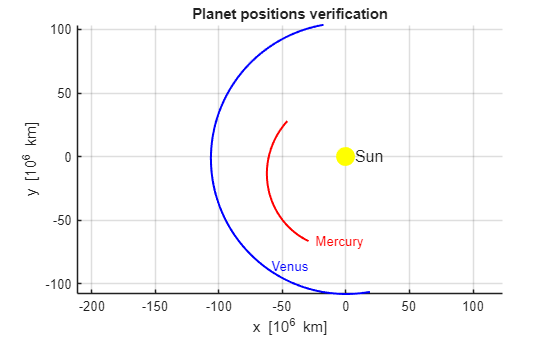


figure('Color','w');
hold on;

% Plot Sun
scatter3(0, 0, 0, 200, 'y', 'filled');
text(0, 0, 0, '  Sun', 'FontSize', 12);

% Plot Venus positions (all departure days, one travel time)
r_V_plot = squeeze(r_Venus_grid(:, 1, :));  % [3 x 365]
plot3(r_V_plot(1,:)/1e6, r_V_plot(2,:)/1e6, r_V_plot(3,:)/1e6, ...
    'b-', 'LineWidth', 1.5);
text(r_V_plot(1,1)/1e6, r_V_plot(2,1)/1e6, r_V_plot(3,1)/1e6, ...
    '  Venus', 'Color','b');

% Plot Mercury positions (all arrival times for departure day 1)
r_M_plot = squeeze(r_Mercury_grid(:, :, 1));  % [3 x 31]
plot3(r_M_plot(1,:)/1e6, r_M_plot(2,:)/1e6, r_M_plot(3,:)/1e6, ...
    'r-', 'LineWidth', 1.5);
text(r_M_plot(1,1)/1e6, r_M_plot(2,1)/1e6, r_M_plot(3,1)/1e6, ...
    '  Mercury', 'Color','r');

axis equal; grid on;
set(gca, 'Color','w');
xlabel('x [10^6 km]'); ylabel('y [10^6 km]'); zlabel('z [10^6 km]');
title('Planet positions verification');

### d) Porkchop plot

%% Task (d) - Porkchop Plot of total Delta-V cost
% Venus (departure) -> Mercury (arrival)
% For each (t_depart, t_travel) node, computes total DV = DV_dep + DV_arr
% for both short and long arc Lambert solutions.

%% --- Pre-allocate DV grids ---
DV_short = nan(size(T_dep));   % [31 x 365]
DV_long  = nan(size(T_dep));   % [31 x 365]

%% --- Main loop ---
for i = 1:size(T_dep,1)        % travel time index
    for j = 1:size(T_dep,2)    % departure day index

        t_d = T_dep(i,j);               % departure time [s]
        t_a = t_d + T_trav(i,j);        % arrival time [s]

        % ---- Planet positions & velocities at departure / arrival ----
        % Venus at departure
        theta_V_dep = functionshw2.propagate(mu_S, a_V0, e_V0, theta_V0, t_d);
        [r1, v1] = functionshw2.coe2rv(a_V0, e_V0, Omega_V0, i_V0, omega_V0, theta_V_dep, mu_S);

        % Mercury at arrival
        theta_M_arr = functionshw2.propagate(mu_S, a_M0, e_M0, theta_M0, t_a);
        [r2, v2] = functionshw2.coe2rv(a_M0, e_M0, Omega_M0, i_M0, omega_M0, theta_M_arr, mu_S);

        r1 = r1(:);  v1 = v1(:);
        r2 = r2(:);  v2 = v2(:);                                                  

        % Time of flight in seconds
        Dt = T_trav(i,j);

        % ---- Normal vectors for short and long arc ----
        k_cross = cross(r1, r2);
        if norm(k_cross) < 1e-6
            continue   % r1 and r2 are collinear, skip
        end
        k_short = k_cross / norm(k_cross);   % short arc
        k_long  = -k_short;                   % long arc

        % ---- Solve Lambert + compute DV for each arc ----
        for arc = 1:2
            if arc == 1
                k = k_short;
            else
                k = k_long;
            end

            try
                % Heliocentric transfer orbit
                [a_tr, e_tr, Om_tr, i_tr, om_tr, th1_tr, th2_tr] = functionshw2.Lambert_solve(mu_S, r1, r2, Dt, k);

                % Velocity of transfer orbit at departure and arrival
                [~, v_dep_tr] = functionshw2.coe2rv(a_tr, e_tr, Om_tr, i_tr, om_tr, th1_tr, mu_S);
                [~, v_arr_tr] = functionshw2.coe2rv(a_tr, e_tr, Om_tr, i_tr, om_tr, th2_tr, mu_S);

                % Hyperbolic excess velocities (relative to planets)
                v_dep_tr = v_dep_tr(:);
                v_arr_tr = v_arr_tr(:);
                vh_dep = v_dep_tr - v1;  vh_dep = vh_dep(:); % excess at Venus (departure)
                vh_arr = -(v_arr_tr - v2);  vh_arr = vh_arr(:); % excess at Mercury (arrival)
                % - added in vh_arr

                % DV for escape from Venus parking orbit
                [~, Dv_dep] = functionshw2.hyperbola(mu_V, a_V, e_V, Omega_V, i_V, 0, vh_dep); % should be parking orbit

                % DV for capture into Mercury parking orbit
                [~, Dv_arr] = functionshw2.hyperbola(mu_M, a_M, e_M, Omega_M, i_M, 0, vh_arr);

                dv_total = norm(Dv_dep) + norm(Dv_arr);

                if arc == 1
                    DV_short(i,j) = dv_total;
                else
                    DV_long(i,j)  = dv_total;
                end

            catch
                % No elliptic solution for this node — leave as NaN
            end
        end
    end
    % Progress indicator (optional - comment out if slow)
    if mod(i,5) == 0
        fprintf('Progress: travel time row %d / %d done\n', i, size(T_dep,1));
    end
end

Progress: travel time row 5 / 31 done


Progress: travel time row 10 / 31 done


Progress: travel time row 15 / 31 done


Progress: travel time row 20 / 31 done


**TEST SECTION**

%% DIAGNOSTIC - test a single node first
ii_test = 16;   % middle travel time (75 days)
jj_test = 1;    % first departure day

r1_test = r_Venus_grid(:, ii_test, jj_test);
r2_test = r_Mercury_grid(:, ii_test, jj_test);
Dt_test = T_trav(ii_test, jj_test);

fprintf('r1 = [%.2f, %.2f, %.2f] km\n', r1_test);
fprintf('r2 = [%.2f, %.2f, %.2f] km\n', r2_test);
fprintf('Dt = %.2f days\n', Dt_test/86400);
fprintf('norm(r1) = %.4e km\n', norm(r1_test));

norm(r1) = 1.0761e+08 km


fprintf('norm(r2) = %.4e km\n', norm(r2_test));

norm(r2) = 6.6679e+07 km


k_test = cross(r1_test, r2_test)/norm(cross(r1_test, r2_test));
fprintf('k = [%.4f, %.4f, %.4f]\n', k_test);

k = [-0.0597, 0.0161, -0.9981]


% Test Lambert
try
    [a_t, e_t, Omega_t, i_t, omega_t, th1_t, th2_t] = functionshw2.Lambert_solve(mu_S, r1_test, r2_test, Dt_test, k_test);
    fprintf('Lambert OK: a=%.4e km, e=%.6f\n', a_t, e_t);

    % Test velocities
    [~, v1_t] = functionshw2.coe2rv(a_t, e_t, Omega_t, i_t, omega_t, th1_t, mu_S);
    [~, v2_t] = functionshw2.coe2rv(a_t, e_t, Omega_t, i_t, omega_t, th2_t, mu_S);
    fprintf('v1_transfer = [%.4f, %.4f, %.4f] km/s\n', v1_t);
    fprintf('v2_transfer = [%.4f, %.4f, %.4f] km/s\n', v2_t);

    % Test planet velocities
    theta_V_dep = functionshw2.propagate(mu_S, a_V0, e_V0, theta_V0, T_dep(ii_test,jj_test));
    [~, v1_V] = functionshw2.coe2rv(a_V0, e_V0, Omega_V0, i_V0, omega_V0, theta_V_dep, mu_S);
    fprintf('v_Venus = [%.4f, %.4f, %.4f] km/s\n', v1_V);

    theta_M_arr = functionshw2.propagate(mu_S, a_M0, e_M0, theta_M0, T_dep(ii_test,jj_test)+Dt_test);
    [~, v2_M] = functionshw2.coe2rv(a_M0, e_M0, Omega_M0, i_M0, omega_M0, theta_M_arr, mu_S);
    fprintf('v_Mercury = [%.4f, %.4f, %.4f] km/s\n', v2_M);

    % Hyperbolic excess velocities
    vh_dep = v1_t - v1_V;
    vh_arr = -(v2_t - v2_M); % - added
    fprintf('vh_dep magnitude = %.4f km/s\n', norm(vh_dep));
    fprintf('vh_arr magnitude = %.4f km/s\n', norm(vh_arr));

    % Test hyperbola
    [theta_burn, Dv_dep] = functionshw2.hyperbola(mu_V, a_V, e_V, Omega_V, i_V, 0, vh_dep);
    [~,          Dv_arr] = functionshw2.hyperbola(mu_M, a_M, e_M, Omega_M, i_M, 0, vh_arr); %-vh_arr
    fprintf('DV_dep = %.4f km/s\n', norm(Dv_dep));
    fprintf('DV_arr = %.4f km/s\n', norm(Dv_arr));
    fprintf('DV_total = %.4f km/s\n', norm(Dv_dep)+norm(Dv_arr));

catch ME
    fprintf('ERROR: %s\n', ME.message);
end

Lambert OK: a=6.8079e+07 km, e=0.948443


v1_transfer = [-19.6577, -11.3891, 0.9918] km/s


v2_transfer = [32.6881, 30.9940, -1.4547] km/s


v_Venus = [27.6183, -21.3356, -1.8968] km/s


v_Mercury = [10.1464, -40.6157, -4.2593] km/s


vh_dep magnitude = 48.3973 km/s


vh_arr magnitude = 75.1262 km/s


DV_dep = 43.4938 km/s


DV_arr = 73.7300 km/s


DV_total = 117.2238 km/s


%% --- Plot Porkchop ---
% Convert departure times from seconds to days for readable axis
dep_days   = t_depart / 86400;   % 0..364 days from Jan 1 2312
trav_days  = t_travel / 86400;   % 60..90 days

% Clamp colorbar range: ignore extreme outliers for clarity
clim_max_short = prctile(DV_short(~isnan(DV_short)), 90);
clim_max_long  = prctile(DV_long (~isnan(DV_long)),  90);
clim_min = 0;

figure('Name','Porkchop Plot - Venus to Mercury','Position',[100 100 1400 600]);

% --- Short arc ---
subplot(1,2,1);
contourf(dep_days, trav_days, DV_short, 40, 'LineStyle','none');
hold on;
contour(dep_days, trav_days, DV_short, 15, 'k', 'LineWidth', 0.5);
colormap(gca, parula);
clim([clim_min, clim_max_short]);

SPOT ERROR IN clim_max_short

if isfinite(clim_max_short) && clim_max_short > 0
    clim([0 clim_max_short]);
else
    clim([0 20]);   % fallback
    fprintf('Warning: clim_max_short is NaN, using default [0, 20]\n');
end

CONT'D PORKCHOP PLOT

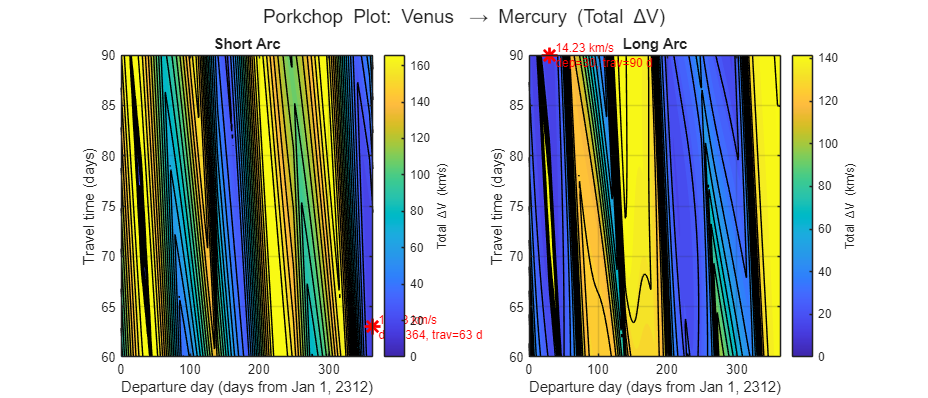

cb = colorbar;
cb.Label.String = 'Total \DeltaV (km/s)';
xlabel('Departure day (days from Jan 1, 2312)');
ylabel('Travel time (days)');
title('Short Arc');
grid on;

% Mark minimum
[min_val_s, idx_s] = min(DV_short(:));
[ri_s, ci_s] = ind2sub(size(DV_short), idx_s);
hold on;
plot(dep_days(ci_s), trav_days(ri_s), 'r*', 'MarkerSize', 12, 'LineWidth', 2);
text(dep_days(ci_s)+3, trav_days(ri_s), ...
    sprintf(' %.2f km/s\n dep=%d, trav=%d d', min_val_s, round(dep_days(ci_s)), round(trav_days(ri_s))), ...
    'Color','red','FontSize',9);

% --- Long arc ---
subplot(1,2,2);
contourf(dep_days, trav_days, DV_long, 40, 'LineStyle','none');
hold on;
contour(dep_days, trav_days, DV_long, 15, 'k', 'LineWidth', 0.5);
colormap(gca, parula);
clim([clim_min, clim_max_long]);
cb = colorbar;
cb.Label.String = 'Total \DeltaV (km/s)';
xlabel('Departure day (days from Jan 1, 2312)');
ylabel('Travel time (days)');
title('Long Arc');
grid on;

% Mark minimum
[min_val_l, idx_l] = min(DV_long(:));
[ri_l, ci_l] = ind2sub(size(DV_long), idx_l);
hold on;
plot(dep_days(ci_l), trav_days(ri_l), 'r*', 'MarkerSize', 12, 'LineWidth', 2);
text(dep_days(ci_l)+3, trav_days(ri_l), ...
    sprintf(' %.2f km/s\n dep=%d, trav=%d d', min_val_l, round(dep_days(ci_l)), round(trav_days(ri_l))), ...
    'Color','red','FontSize',9);

sgtitle('Porkchop Plot: Venus \rightarrow Mercury (Total \DeltaV)', 'FontSize', 14);

%% --- Print optima ---
fprintf('\n=== Short Arc Optimum ===\n');


=== Short Arc Optimum ===


fprintf('Departure day: %d (day of year 2312)\n', round(dep_days(ci_s)));

Departure day: 364 (day of year 2312)


fprintf('Travel time:   %d days\n', round(trav_days(ri_s)));

Travel time:   63 days


fprintf('Total DV:      %.4f km/s\n', min_val_s);

Total DV:      17.3339 km/s


fprintf('\n=== Long Arc Optimum ===\n');


=== Long Arc Optimum ===


fprintf('Departure day: %d (day of year 2312)\n', round(dep_days(ci_l)));

Departure day: 30 (day of year 2312)


fprintf('Travel time:   %d days\n', round(trav_days(ri_l)));

Travel time:   90 days


fprintf('Total DV:      %.4f km/s\n', min_val_l);

Total DV:      14.2297 km/s


Checking validity of results

%% --- Debug: check how many valid solutions we got ---
fprintf('Short arc: %d valid nodes out of %d\n', sum(~isnan(DV_short(:))), numel(DV_short));

Short arc: 11315 valid nodes out of 11315


fprintf('Long arc:  %d valid nodes out of %d\n', sum(~isnan(DV_long(:))),  numel(DV_long));

Long arc:  11315 valid nodes out of 11315


fprintf('Short arc DV range: %.4f to %.4f km/s\n', min(DV_short(:)), max(DV_short(:)));

Short arc DV range: 17.3339 to 176.2684 km/s


fprintf('Long arc  DV range: %.4f to %.4f km/s\n', min(DV_long(:)),  max(DV_long(:)));

Long arc  DV range: 14.2297 to 175.8880 km/s


%% Check 1: Are your planet velocities correct?
% Venus circular orbital speed should be ~35 km/s
% Mercury orbital speed should be ~47 km/s
fprintf('Venus orbital speed: %.2f km/s (expected ~35)\n', norm(v1_V));

Venus orbital speed: 34.95 km/s (expected ~35)


fprintf('Mercury orbital speed: %.2f km/s (expected ~47)\n', norm(v2_M));

Mercury orbital speed: 42.08 km/s (expected ~47)


%% Check 2: Are vh magnitudes realistic?
% vh_dep and vh_arr should be ~3-10 km/s for inner solar system
fprintf('vh_dep magnitude: %.2f km/s (expected 3-10)\n', norm(vh_dep));

vh_dep magnitude: 48.40 km/s (expected 3-10)


fprintf('vh_arr magnitude: %.2f km/s (expected 3-10)\n', norm(vh_arr));

vh_arr magnitude: 75.13 km/s (expected 3-10)


%% Check 3: Are parking orbit ΔV realistic?
% Each burn should be ~1-5 km/s
fprintf('DV_dep: %.2f km/s (expected 1-5)\n', norm(Dv_dep));

DV_dep: 43.49 km/s (expected 1-5)


fprintf('DV_arr: %.2f km/s (expected 1-5)\n', norm(Dv_arr));

DV_arr: 73.73 km/s (expected 1-5)


%% Check 4: mu_S units
% mu_S should be 1.327124e11 km^3/s^2
fprintf('mu_S = %.4e km^3/s^2 (expected 1.327e11)\n', mu_S);

mu_S = 1.3271e+11 km^3/s^2 (expected 1.327e11)


% Check transfer orbit velocity magnitudes
fprintf('v1_transfer magnitude: %.2f km/s\n', norm(v1_t));  % should be ~30-40 km/s

v1_transfer magnitude: 22.74 km/s


fprintf('v2_transfer magnitude: %.2f km/s\n', norm(v2_t));  % should be ~40-60 km/s

v2_transfer magnitude: 45.07 km/s


fprintf('v1_Venus magnitude:    %.2f km/s\n', norm(v1_V));  % ~35 km/s

v1_Venus magnitude:    34.95 km/s


fprintf('v2_Mercury magnitude:  %.2f km/s\n', norm(v2_M));  % ~47 km/s

v2_Mercury magnitude:  42.08 km/s


% Check vh components
fprintf('\nvh_dep = [%.2f, %.2f, %.2f] km/s\n', vh_dep);


vh_dep = [-47.28, 9.95, 2.89] km/s


fprintf('vh_arr = [%.2f, %.2f, %.2f] km/s\n', vh_arr);

vh_arr = [22.54, 71.61, 2.80] km/s


% Check transfer orbit elements
fprintf('\nTransfer orbit:\n');


Transfer orbit:


fprintf('a = %.4e km\n', a_t);

a = 6.8079e+07 km


fprintf('e = %.6f\n', e_t);

e = 0.948443


fprintf('theta1 = %.4f deg\n', rad2deg(th1_t));

theta1 = 170.8779 deg


fprintf('theta2 = %.4f deg\n', rad2deg(th2_t));

theta2 = 198.8765 deg


% Full velocity check
fprintf('v1_transfer = [%.4f, %.4f, %.4f] km/s,  mag = %.4f\n', v1_t, norm(v1_t));

v1_transfer = [-19.6577, -11.3891, 0.9918] km/s,  mag = 22.7403


fprintf('v2_transfer = [%.4f, %.4f, %.4f] km/s,  mag = %.4f\n', v2_t, norm(v2_t));

v2_transfer = [32.6881, 30.9940, -1.4547] km/s,  mag = 45.0694


fprintf('v1_Venus    = [%.4f, %.4f, %.4f] km/s,  mag = %.4f\n', v1_V, norm(v1_V));

v1_Venus    = [27.6183, -21.3356, -1.8968] km/s,  mag = 34.9510


fprintf('v2_Mercury  = [%.4f, %.4f, %.4f] km/s,  mag = %.4f\n', v2_M, norm(v2_M));

v2_Mercury  = [10.1464, -40.6157, -4.2593] km/s,  mag = 42.0800


% Vis-viva check at theta2
r2_mag = norm(r2_test);
v2_visviva = sqrt(mu_S*(2/r2_mag - 1/a_t));
fprintf('\nvis-viva speed at r2:     %.4f km/s\n', v2_visviva);


vis-viva speed at r2:     45.0694 km/s


fprintf('norm(v2_transfer):        %.4f km/s\n', norm(v2_t));

norm(v2_transfer):        45.0694 km/s


fprintf('(should match)\n');

(should match)


% Check r2 is consistent with theta2
p_t = a_t*(1-e_t^2);
r2_from_theta2 = p_t/(1+e_t*cos(th2_t));
fprintf('\nnorm(r2_Mercury) = %.4e km\n', norm(r2_test));


norm(r2_Mercury) = 6.6679e+07 km


fprintf('r(theta2)        = %.4e km\n', r2_from_theta2);

r(theta2)        = 6.6679e+07 km


fprintf('(should match - if not, theta2 is wrong)\n');

(should match - if not, theta2 is wrong)


%  Try long arc instead of short for heliocentric transfer
k_helio = -cross(r1, r2)/norm(cross(r1, r2));  % flip to long arc
[a_t, e_t, Omega_t, i_t, omega_t, th1_t, th2_t] = ...
    functionshw2.Lambert_solve(mu_S, r1, r2, Dt, k_helio);

[~, v1_t] = functionshw2.coe2rv(a_t, e_t, Omega_t, i_t, omega_t, th1_t, mu_S);
[~, v2_t] = functionshw2.coe2rv(a_t, e_t, Omega_t, i_t, omega_t, th2_t, mu_S);

vh_dep_long = v1_t - v1_V;
vh_arr_long = -(v2_t - v2_M); % - added

fprintf('vh_dep (long arc) = %.2f km/s\n', norm(vh_dep_long));

vh_dep (long arc) = 34.79 km/s


fprintf('vh_arr (long arc) = %.2f km/s\n', norm(vh_arr_long))

vh_arr (long arc) = 92.19 km/s


% Check angular separation between Mercury and transfer arrival point
% If Mercury is far from where the spacecraft arrives, vh_arr will be huge

% Position on transfer orbit at theta2
p_t = a_t*(1-e_t^2);
r2_transfer_mag = p_t/(1+e_t*cos(th2_t));

% Get actual Mercury position vector at arrival
fprintf('r2_Mercury direction: [%.4f, %.4f, %.4f]\n', r2_test/norm(r2_test));

r2_Mercury direction: [-0.9053, -0.4221, 0.0473]


% Get transfer orbit arrival position
[r2_transfer_vec, ~] = functionshw2.coe2rv(a_t, e_t, Omega_t, i_t, omega_t, th2_t, mu_S);
fprintf('r2_transfer direction: [%.4f, %.4f, %.4f]\n', r2_transfer_vec/norm(r2_transfer_vec));

r2_transfer direction: [-0.9959, -0.0053, 0.0898]


% Angular separation
cos_angle = dot(r2_test/norm(r2_test), r2_transfer_vec/norm(r2_transfer_vec));
fprintf('Angle between Mercury and transfer arrival: %.2f deg\n', rad2deg(acos(cos_angle)));

Angle between Mercury and transfer arrival: 24.76 deg


% Also plot Mercury orbit and transfer orbit to see visually
figure('Color','w');
theta_plot = linspace(0, 2*pi, 500);
p_t_val = a_t*(1-e_t^2);
r_transfer = p_t_val ./ (1 + e_t*cos(theta_plot));

% This will show if Mercury and transfer orbit intersect properly
fprintf('\nMercury distance from Sun: %.4e km\n', norm(r2_test));


Mercury distance from Sun: 6.6679e+07 km


fprintf('Transfer orbit at theta2:  %.4e km\n', r2_transfer_mag);

Transfer orbit at theta2:  6.0973e+07 km


fprintf('(these match by construction - the orbit passes through Mercury position)\n');

(these match by construction - the orbit passes through Mercury position)


fprintf('\nBut Mercury VELOCITY direction vs transfer velocity direction:\n');


But Mercury VELOCITY direction vs transfer velocity direction:


fprintf('dot(v2_Mercury_hat, v2_transfer_hat) = %.4f\n', dot(v2_M/norm(v2_M), v2_t/norm(v2_t)));

dot(v2_Mercury_hat, v2_transfer_hat) = -0.9790


fprintf('(+1 = same direction, -1 = opposite → explains huge vh_arr)\n');

(+1 = same direction, -1 = opposite → explains huge vh_arr)
